# Memory 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

One advantage of programming over performing computations by hand is the ability to access large amounts of stored data. This stored information is called *memory. *There are different types of memory in computers, such as L1 or L2 caches, RAM (random access memory), or, for longer-term storage, a hard drive or solid-state drive. Unless you become a professional programmer, you probably won't have to worry about the details of these types of storage, but understanding a little bit about how programs interact with memory can help you to write efficient programs or to understand why an algorithm might be much faster in some implementations than others. 

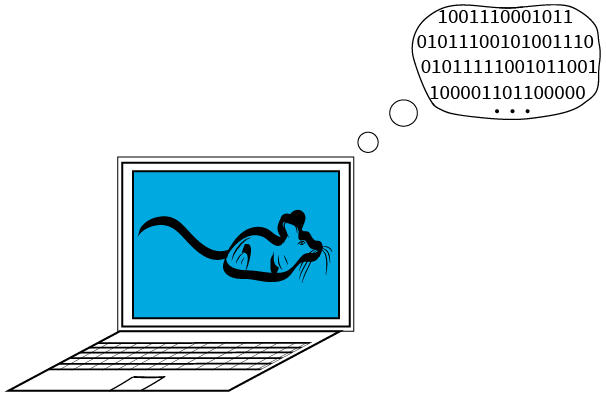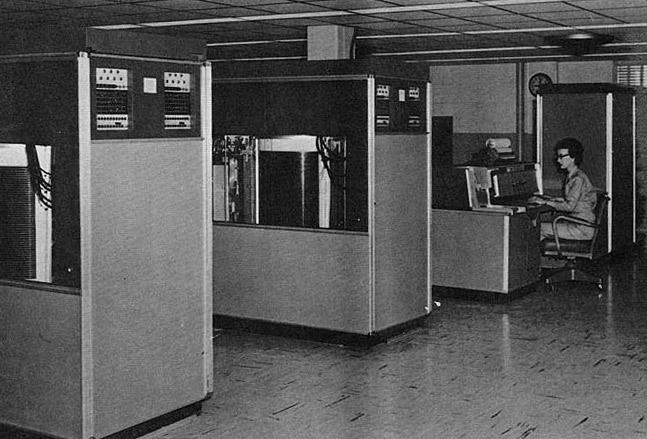

Photo credit: By User RTC on en.wikipedia - [Photo by U. S. Army Red River Arsenal, Public Domain](https://commons.wikimedia.org/w/index.php?curid=1079125)

 While a modern programmer has incredible amounts of memory to work with, especially compared to the two state-of-the-art IBM 350 RAMAC hard drives shown that stored 7.5 megabytes altogether, thinking about how you store and access your data can significantly impact your results. 

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

## Memory Usage

A bit is the least amount of binary information that can be stored or communicated by a classical digital computer. A byte is the smallest unit of memory that a computer's operating system can address. While the IBM 350 RAMAC shown above used a 6-bit structure, the current standard value of a byte is 8 bits, although specialized hardware may choose to be built to different specifications. Modern personal computers have built-in memory in the gigabyte (GB) range which is $10^9$ bytes. This script will use the standard 1 byte = 8 bits throughout.

** Exercise 1.**

Replace the value 0 with the correct answer for each question. Then run this section to check your solutions. You may want to review the information about [integers](https://www.mathworks.com/help/matlab/matlab_prog/integers.html) and [floating point numbers](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) in the MATLAB documentation. 

a) How many bytes are required to represent a double-precision floating point number?

answer1a = 0;  % Replace the 0 with the actual number of bytes

b) How many bytes are required to represent a single-precision floating point number?

answer1b = 0; % Replace the 0 with the actual number of bytes

c) What is the minimum number of bytes required to represent the number 203?

answer1c = 0; % Replace the 0 with the actual number of bytes

d) What is the minimum number of bytes required to represent the number -203?

answer1d = 0; % Replace the 0 with the actual number of bytes

CheckExercise1(answer1a,answer1b,answer1c,answer1d);

## Storing Arrays

An array is allocated as a single block of memory of a known size divided into equal-sized pieces. For an `m-by-n` array of doubles, there is a block of memory of size `mxnx64` bits. This makes indexing into the array a very efficient operation because reaching the memory location requires knowing the starting address for the memory and then adding an offset based on the index and the size of the pieces. This means that changing the entries in an array is quick. However, if you want to add an element to an array, this requires three steps. 

- Allocate a new block of memory of a larger size in a new place. 

- Copy all the data to the new locations. 

- Add the new data to the array. 

### MATLAB is [Column-Major](https://www.mathworks.com/help/coder/ug/what-are-column-major-and-row-major-representation-1.html) by Default

Computer memory is indexed linearly, so every language must choose how to reshape the data into a linear format for storage. MATLAB uses a column-major layout by default. This means that, for instance, it is far more efficient to reshape a matrix into a stack of columns--because no data has to move--rather than into a line of rows where nearly all the data will have to move to a new position. 

#### Illustrative Example

% Clear the workspace, so previous work isn't impacting your results
clearvars()
% Set the seed for the random number generator for repeatability
rng(123)

% Set up two random nxn matrices
n = 1000;
A = randi(9,n);
B = randi(9,n);

% Compute the product AB using built-in matrix multiplication
correct = A*B;

The built-in matrix multiplication is highly optimized. Try computing the product $AB$ using a hand-written algorithm for matrix multiplication so we can see exactly what steps are occurring. 

- First index the rows, then the columns

tic
P = zeros(n);
for j = 1:n
    for k = 1:n
        s = 0;
        for kk = 1:n
            s = s + A(j,kk)*B(kk,k);
        end
        P(j,k) = s;
    end
end
t1 = toc

Ensure that the different algorithms are computing the same value. 

if isequal(P,correct)
    disp("The hand-written algorithm computes the same value as the built-in matrix multiplication.")
else
    disp("The algorithms compute different values.")
end
% Clear the helper variables
clearvars P s j k kk
whos

Try computing the product $AB$ again using the same hand-written algorithm for matrix multiplication but with one tiny switch.

          2. First index the columns, then the rows

tic
P = zeros(n);
for k = 1:n
    for j = 1:n
        s = 0;
        for kk = 1:n
            s = s + A(j,kk)*B(kk,k);
        end
        P(j,k) = s;
    end
end
t2 = toc

Ensure that the different algorithms are computing the same value, i.e., we didn't change the answer by switching the indices. 

if isequal(P,correct)
    disp("The hand-written algorithm computes the same value as the built-in matrix multiplication.")
else
    disp("The algorithms compute different values.")
end
% Visualize the timing
bar([t1 t2])
title("Time spent to multiply "+n+" by "+n+" matrices")
xticklabels(["Row-Column" "Column-Row"])
xtickangle(30)
ylabel("Time (s)")
percentSlower = round((t2-t1)/t1*100,1);
subtitle("Column-Row is "+ percentSlower + "% slower than Row-Column")

This is a toy example because, hopefully, you are not planning to reimplement basic matrix multiplication on your own. The underlying idea is that there are many ways to solve a programming problem. What may appear to be minor design choices can significantly impact execution speed, amount of memory used, etc. 

## Pre-Allocating Arrays

By pre-allocating an array, you can ensure that an appropriate amount of memory has been set aside for your calculation, and then you can access only the parts of it that you need at each step, as shown here:

n = 1000;                        % Choose the size of the matrices to work with

#### Pre-allocating memory for `M2` and `newCol`

tic                              % Start a timer
M = zeros(n-10,n);               % Pre-allocate the matrix M
for j = 1:(n-10)
    M(j,:) = (1:n)*10-j+1;       % Write the jth row
end
Mtime = toc                      % Stop the timer
M(1:10,1:6)                      % Display the first few entries of matrix M

## Dynamically Allocating Arrays

If you do not set the size of an array to start with, even if you end up with the same result, the memory operations required can have a significant impact, even on a toy example. Here, we generate another matrix of random-valued entries of the same size, but in a dynamic fashion where we build each column by concatenation and then concatenate that column to the earlier array. Because there is no pre-allocation of memory to contain the matrix `N`, each time a `newCol` is concatenated onto `N`, a new block of memory has to be allocated and all the values copied over. This is not very noticeable for small values of `n`, but as `n` gets larger, the effect is quite clear.

#### Without Pre-allocating Memory

tic                                      % Start a timer
for k = 1:(n-10)
    N(k,:) = (1:n)*10-k+1;               % Assign the kth row of values
end
Ntime = toc                              % Stop the timer
N(1:10,1:6)                              % Display the matrix N
clearvars N                              % So re-testing will occur without pre-allocation

Observe that there are auto-generated warnings on the lines where we set the values for `newCol` and `N` in this version. To learn more about the Code Analyzer, please check out the [documentation](https://www.mathworks.com/help/matlab/matlab_prog/check-code-for-errors-and-warnings.html) or take the [MATLAB Programming Techniques](https://matlabacademy.mathworks.com/details/matlab-programming-techniques/mlpr) course, which has a module on using the [MATLAB Code Analyzer](https://matlabacademy.mathworks.com/R2021b/portal.html?course=mlpr#chapter=8&lesson=3&section=1).

### Compare the results

By timing each operation, we can compare the results. What do you see?

NMratio = Ntime/Mtime                   % Compare the times

  **Try**.

- Modify the commands that create `M2` so that `newCol` is not pre-allocated, then run the code again. How much of an impact does that have on your results?

- Modify the commands that create `M` so that the matrix is filled in row by row rather than column by column. How much of an impact does that have on your results? 

## Use Dimension Carefully

As you can see, code that requires moving memory around can be quite slow. Clever programming can allow you to be as efficient as possible. 

### Implicit Expansion

MATLAB tries to help you avoid unnecessary memory use by supporting implicit expansion of arrays. We used implicit expansion in the memory allocation example to create each row of values. 

Q = [1 2 3; 4 5 6];
T = [1; -1];

Now, `Q` is a `2x3` matrix, and `T` is a `2x1` matrix, so by the rules of mathematics, it isn't possible to compute `Q+T`. MATLAB trusts that you know what you are doing, however, and implicitly expands `T` to become 

so it will match the dimensions of `Q,` and we can execute

Q+T

without ever creating the larger array of 3 copies of `T` in memory. 

The limitation here is that MATLAB will expand along any scalar dimension if doing such replication will allow an operation to be mathematically correct. It may not be what you have in mind as the programmer at all, especially if you didn't realize that you have created both row and column vectors:

V = [1 5]
T+V

### Dimension Arguments

If you consider a series of commands like

mean(M)
mean(M,2)
mean(M,"all")

it is clear that the default orientation for `mean`, like all MATLAB functions, is to operate column-wise. If you want a row-wise computation of mean values, you can specify an optional dimensions argument. Similarly, suppose you have a collection of comparable data organized into a tabular shape. In that case, you might want to compute the mean value of all the elements in a matrix using the dimensions argument `"all"`.

** Exercise 2.**

- Hypothesize about whether it will be faster to use a dimensional argument or to transpose a matrix such as `M` before using a standard function. Why or why not? 

- Time the computation of the [standard deviation](https://www.mathworks.com/help/matlab/ref/std.html) of `M` along each row using a dimensional argument or by [transposition](https://www.mathworks.com/help/matlab/ref/transpose.html) without a dimensional argument. Were you correct about your hypothesis?

## Further Exploration

### MATLAB Memory Allocation

You can learn more details about [MATLAB memory allocation](https://www.mathworks.com/help/matlab/matlab_prog/memory-allocation.html), such as lazy copying, or more about how different data types are stored in the documentation.  

### Compression & Encoding

Depending on the data you are working with, you may also be more efficient with your memory use by using various forms of compression One example is the [sparse matrix format](https://www.mathworks.com/help/matlab/ref/sparse.html).

### Parallel Computing

One of the most efficient structures for some common types of computationally- or data-intensive problems is addressed by the idea of [parallel computing](https://www.mathworks.com/help/parallel-computing/what-is-parallel-computing.html). In this case, you set up the same (or completely independent) operations in parallel on different bits of data. Various types of specialized hardware facilitate parallel computing. There are also programmatic structures that make such code easier to write and run. As you can imagine, this involves all sorts of interesting challenges related to memory.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))